# Part2 Multi-Antenna Operation

## Maximum Ratio Combining

clear all; clc;
function [radio_Tx,radio_Rx] = USRP_init(rx_length)

platform = "N200/N210/USRP2";
address  = '192.168.10.2';
USRPGain            = 5;  
USRPCenterFrequency = 885*1e6;  

radio_Tx = comm.SDRuTransmitter(...
    'Platform',             platform, ... 
    'IPAddress',            address, ...
    'CenterFrequency',      USRPCenterFrequency, ...
    'Gain',                 USRPGain, ...
    'InterpolationFactor',  100);

radio_Rx = comm.SDRuReceiver(...
    'Platform',             "B210", ...
    'SerialNum',            "315EEDF", ...
    'CenterFrequency',      USRPCenterFrequency, ...
    'Gain',                 20, ...
    'SamplesPerFrame',      rx_length, ...
    'ChannelMapping',       [1, 2], ...
    'MasterClockRate',      20e6, ...
    'DecimationFactor',     20, ...
    'OutputDataType',       'double') ; 

end

%Part2(1)(2);
%parameters:
Nfft = 64;
N_CP = 16;
Fs = 1e6;
M = 16;
numDataSym = 100;
N_frames = 10;
threshold = 1e-6; %power threshold
N_trans = 100; %transmit 2000 times

all_sc = [-26:-1 0 1:26]; %52 tones in total
pilots_sc = [-21 -7 7 21]; %4 pilot tones
data_sc = setdiff(all_sc, pilots_sc); 
data_sc(data_sc == 0) = [];% 48 data tones
toIdx = @(k)  mod(k, Nfft)+1;

%Generate 100 OFDM symbol
%Zero padding
Pre_pad = zeros(1,100);
Post_pad = zeros(1,100);

% STS
S_used = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
    0, 0, 0, 0, 0 ,0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
X_STS = zeros(1, Nfft);
X_STS(toIdx(all_sc)) = S_used;   
x_sts64  = ifft(X_STS, Nfft);      
x_sts16 = x_sts64(1:16);         
x_sts160 = repmat(x_sts16, 1, 10);

% LTS
L_used = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1,...
    -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1,-1,1,1,-1,-1,1,-1,1,-1,1,1,1,1] ;   
X_LTS = zeros(1, Nfft);
X_LTS(toIdx(all_sc)) = L_used;
x_lts      = ifft(X_LTS, Nfft);
x_lts160 = [x_lts(end-2*N_CP+1:end), x_lts, x_lts]; 

frame_data = [];
txBits = cell(1, numDataSym); 
pilotSym  = cell(1, numDataSym);                  

% 100 OFDM symbol
for nSym = 1:numDataSym
    X_ofdm = zeros(1, Nfft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    X_ofdm(toIdx(pilots_sc)) = pilot_sym; 
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 4-QAM 
    data_bits = randi([0 1], 48*log2(M), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, M, 'InputType','bit', 'UnitAveragePower', true);
    X_ofdm(toIdx(data_sc)) = data_sym.'; 

    x_ofdm = ifft(X_ofdm, Nfft);
    x_cp_ofdm   = [x_ofdm(end-N_CP+1:end), x_ofdm];
    frame_data = [frame_data, x_cp_ofdm]; 
end
% combine: 
tx_frame = [Pre_pad, x_sts160, x_lts160, frame_data, Post_pad];
rx_length = 3 * numel(tx_frame);
[radio_Tx, radio_Rx] = USRP_init(rx_length);
count = 0;
rx_buffer_1 = zeros(N_frames, rx_length);
rx_buffer_2 = zeros(N_frames, rx_length);
for k = 1:N_trans %N_trans = 2000
    tunderrun = radio_Tx(tx_frame(:));       % send k-th signal
    [rx_frame, ~, toverflow] = step(radio_Rx); % receive signal
    if toverflow, continue; end
    rx_frame1 = rx_frame(:,1).';  
    rx_frame2 = rx_frame(:,2).';
    Power_1 = mean(abs(rx_frame1).^2);
    Power_2 = mean(abs(rx_frame2).^2);
    if k == 1
        Noise_power_1 = mean(abs(rx_frame1).^2);
        Noise_power_2 = mean(abs(rx_frame2).^2);
    end
    if Power_1 > threshold || Power_2 > threshold
        count = count + 1;
        rx_buffer_1(count,:) = rx_frame1(:).';
        rx_buffer_2(count,:) = rx_frame2(:).';
    end
    if count == N_frames
        break;
    end
end
release(radio_Tx);
release(radio_Rx);

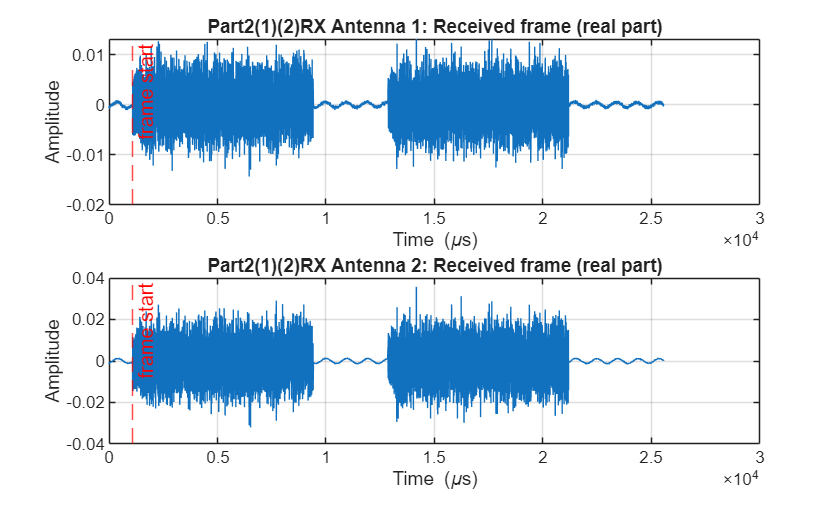

function [start_STS, f] = find_startSTS(rx_buffer)
    N_frames = 10;
    Nfft = 64;
    N_CP = 16;

    all_sc = [-26:-1 0 1:26]; %52 tones in total
    pilots_sc = [-21 -7 7 21]; %4 pilot tones
    data_sc = setdiff(all_sc, pilots_sc); 
    data_sc(data_sc == 0) = [];% 48 data tones
    toIdx = @(k)  mod(k, Nfft)+1;

    % STS
    S_used = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
        0, 0, 0, 0, 0 ,0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
    X_STS = zeros(1, Nfft);
    X_STS(toIdx(all_sc)) = S_used;   
    x_sts64  = ifft(X_STS, Nfft);      
    x_sts16 = x_sts64(1:16);         
    x_sts160 = repmat(x_sts16, 1, 10);

    % LTS
    L_used = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1,...
        -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1,-1,1,1,-1,-1,1,-1,1,-1,1,1,1,1] ;   
    X_LTS = zeros(1, Nfft);
    X_LTS(toIdx(all_sc)) = L_used;
    x_lts      = ifft(X_LTS, Nfft);
    rx_length = numel(rx_buffer);
    for i = 2:N_frames
    
        f = rx_buffer(i,:);
        lts_noCP = [x_lts, x_lts].';        % length 128
        h_mf = conj(flipud(lts_noCP));      % match filter
        mf   = conv(f(:), h_mf, 'full');    % convolution
        a    = abs(mf);
        [pks, locs] = findpeaks(a, 'MinPeakDistance', 64);
        mx = max(pks);
        keep = pks >= 0.9*mx;                             
        locs = locs(keep);
        pk = locs(1); 
    
        data_end = pk-1 + 100*(Nfft+N_CP);
        start_LTS_noCP = pk - (numel(lts_noCP) - 1);
        LEN_LTS_noCP   = numel(lts_noCP);                          % 128
        LEN_STS        = numel(x_sts160);                          % 160
        start_STS      = start_LTS_noCP - (LEN_STS + 2*N_CP);
        start_DATA     = start_LTS_noCP + LEN_LTS_noCP;
    
        if  data_end < rx_length && start_STS > 0
            break;
        end
    end  
end
[start_sts_1 ,f_1] = find_startSTS(rx_buffer_1);
[start_sts_2 ,f_2] = find_startSTS(rx_buffer_2);
%% --- Plot ---
figure; 
subplot(2,1,1);
t_sig_1   = (0:length(f_1)-1)/Fs*1e6;
plot(t_sig_1, real(f_1), 'LineWidth', 1.0); grid on;
xlabel('Time (\mus)'); ylabel('Amplitude');
title('Part2(1)(2)RX Antenna 1: Received frame (real part)');
xline((start_sts_1)/Fs*1e6,'--r','frame start');
subplot(2,1,2);
t_sig_2 = (0:length(f_2)-1)/Fs*1e6;
plot(t_sig_2, real(f_2), 'LineWidth', 1.0); grid on;
xlabel('Time (\mus)'); ylabel('Amplitude');
title('Part2(1)(2)RX Antenna 2: Received frame (real part)');
xline((start_sts_2)/Fs*1e6,'--r','frame start');

fprintf('Start indices of frame#1:%d\nStart indices of frame#2:%d',start_sts_1, start_sts_2);

Start indices of frame#1:1092
Start indices of frame#2:1092

The result shows that the two indices are the same.

%Part2(3)(4)

function [X_data_noCPE, X_data_CPEcorr, X_EQ_noCPE, SNR_sc_dB, H_est] = CFO_correction(start_sts, f, Noise_power, pilotSym)
    %parameter
    numDataSym = 100;
    Fs = 1e6;
    Nfft = 64;
    N_CP = 16;
    all_sc = [-26:-1 0 1:26];
    pilots_sc = [-21 -7 7 21];
    data_sc = setdiff(all_sc, pilots_sc);
    data_sc(data_sc == 0) = [];
    toIdx = @(k) mod(k, Nfft) + 1;
    L_used = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1, ...
        1,-1,1,1,1,1,0,1, -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1, ...
        -1,1,1,-1,-1,1,-1,1,-1,1,1,1,1];
    X_LTS = zeros(1, Nfft);
    X_LTS(toIdx(all_sc)) = L_used;

    LEN_STS      = 160;      % 10×16
    LEN_CP_LTS   = 2*N_CP;   % 32
    L            = 64;       % 
    % LTS(noCP)
    start_LTS_noCP = start_sts + LEN_STS + LEN_CP_LTS;
    LTS1 = f(start_LTS_noCP       + (0:L-1));
    LTS2 = f(start_LTS_noCP +  L  + (0:L-1));
    
    % CFO estimation
    num = sum(LTS2 .* conj(LTS1));
    phi = angle(num);
    cfo_hat_Hz = phi * Fs / (2*pi*L);
    
    %CFO correction
    n     = (0:length(f)-1).';
    f_cfo = (f(:) .* exp(-1j*2*pi*cfo_hat_Hz*n/Fs)).';   % row vector
    
    % LTS-based channel estimation
    y_lts1 = f_cfo(start_LTS_noCP       + (0:Nfft-1));
    y_lts2 = f_cfo(start_LTS_noCP + Nfft + (0:Nfft-1));
    
    Y_lts1 = fft(y_lts1, Nfft);
    Y_lts2 = fft(y_lts2, Nfft);
    
    H_est_1 = zeros(1, Nfft);
    H_est_2 = zeros(1, Nfft);
    
    H_est_1(toIdx(all_sc)) = Y_lts1(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
    H_est_2(toIdx(all_sc)) = Y_lts2(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
    
    H_est = 0.5*(H_est_1 + H_est_2);
    Es = 1; 
    SNR_sc_lin = zeros(1, Nfft);
    H_used = H_est(toIdx(all_sc));
    SNR_sc_lin(toIdx(all_sc)) = (abs(H_used).^2 * Es) ./ Noise_power;
    SNR_sc_dB = 10*log10(SNR_sc_lin + eps);
    
    LEN_LTS_noCP = 2*L;
    start_DATA   = start_LTS_noCP + LEN_LTS_noCP;
    
    X_EQ_noCPE = zeros(numDataSym, Nfft);
    X_EQ_CPEcorr = zeros(numDataSym, Nfft);
    phi_pilot = zeros(1, numDataSym);
    for nSym = 1:numDataSym
        s0   = start_DATA + (nSym-1)*(Nfft+N_CP);
        y_td = f_cfo(s0 + N_CP + (0:Nfft-1));   % remove CP
        Y_fd = fft(y_td, Nfft);
    
        X_eq = zeros(1, Nfft);
        X_eq(toIdx(all_sc)) = Y_fd(toIdx(all_sc)) ./ (H_est(toIdx(all_sc)) + 1e-12);
    
        X_EQ_noCPE(nSym, :) = X_eq;
        % position of 4 pilot, estimate residual phase error
        Rp = X_eq(toIdx(pilots_sc));        % pilot after equalization
        Pk = pilotSym{nSym}(:).';              % known pilot from transmitter
        phi = angle(sum(Rp .* conj(Pk)));   % phase difference
        phi_pilot(nSym) = phi;

        % remove CPE
        X_EQ_CPEcorr(nSym, :) = X_eq * exp(-1j * phi);
    end
    % take the data part out
    X_data_noCPE = X_EQ_noCPE(:, toIdx(data_sc));
    X_data_CPEcorr = X_EQ_CPEcorr(:, toIdx(data_sc));
end

%call the function
[X_data1_noCPE, X_data1_CPEcorr, X_EQ1_noCPE, SNR1_dB, H1_est] = CFO_correction(start_sts_1, f_1, Noise_power_1, pilotSym);
[X_data2_noCPE, X_data2_CPEcorr, X_EQ2_noCPE, SNR2_dB, H2_est] = CFO_correction(start_sts_2, f_2, Noise_power_2, pilotSym);

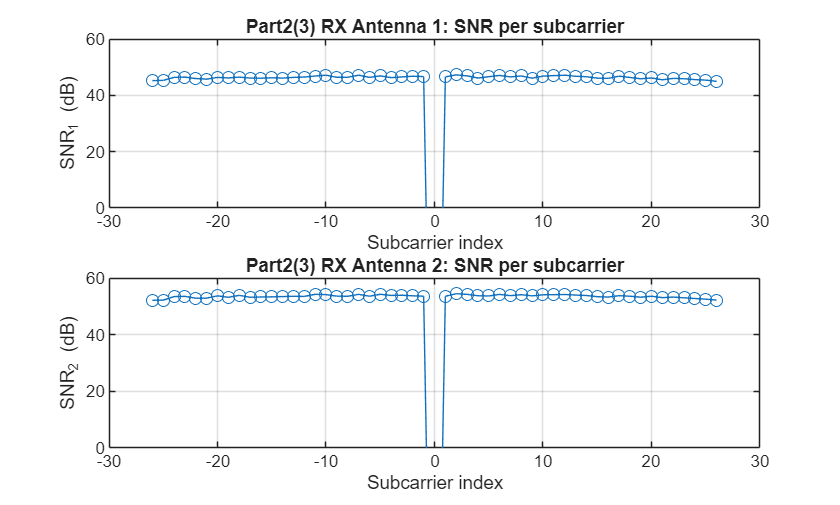

%plot the SNR per subcarrier in (3)
figure;
subplot(2,1,1);
plot(all_sc, SNR1_dB(toIdx(all_sc)), 'o-'); grid on;
xlabel('Subcarrier index'); ylabel('SNR_1 (dB)');
title('Part2(3) RX Antenna 1: SNR per subcarrier');
ylim([0 60]);
subplot(2,1,2);
plot(all_sc, SNR2_dB(toIdx(all_sc)), 'o-'); grid on;
xlabel('Subcarrier index'); ylabel('SNR_2 (dB)');
title('Part2(3) RX Antenna 2: SNR per subcarrier');
ylim([0 60]);

**Observation**

**Both receive antennas exhibit frequency-selective SNR across the OFDM subcarriers**.

- **RX Antenna 1** shows a higher overall SNR (about **50.5–52.3 dB**), indicating a stronger and cleaner channel.

- **RX Antenna 2** shows a lower SNR (around **45–47 dB**), suggesting weaker reception or additional attenuation on this branch.

RX Antenna 1 is about 5 db (about $\sqrt{10}$ times) larger than RX Antenna 2. Compared to the plot in (1) and (2), the magnitude of RX Antenna 1 is about $1\ldotp 78\approx \sqrt{\sqrt{10}}$ time larger than RX Antenna 2. Therefore, we verified that our measurement is correct by comparing to the figure in part 2 (1). 

In both cases, the SNR tends to be **slightly higher near the center subcarriers and lower toward the band edges**, which is expected due to the USRP front-end and analog filters. The fluctuations across subcarriers also indicate **frequency-selective fading**, meaning the wireless channel does not affect all tones equally.

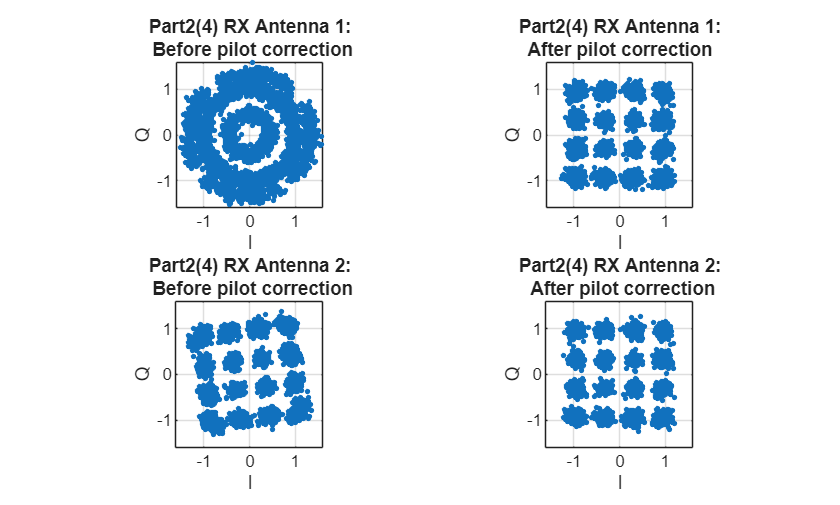

%plot the equalized ofdm in constellation in (4)
figure;
subplot(2,2,1);
plot(real(X_data1_noCPE(:)), imag(X_data1_noCPE(:)), '.', 'MarkerSize', 8);
title({'Part2(4) RX Antenna 1:';' Before pilot correction'});
xlabel('I'); ylabel('Q'); grid on; axis equal;
xlim([-1.6 1.6]); ylim([-1.6 1.6]);

subplot(2,2,2);
plot(real(X_data1_CPEcorr(:)), imag(X_data1_CPEcorr(:)), '.', 'MarkerSize', 8);
title({'Part2(4) RX Antenna 1:';'After pilot correction'});
xlabel('I'); ylabel('Q'); grid on; axis equal;
xlim([-1.6 1.6]); ylim([-1.6 1.6]);
subplot(2,2,3);
plot(real(X_data2_noCPE(:)), imag(X_data2_noCPE(:)), '.', 'MarkerSize', 8);
title({'Part2(4) RX Antenna 2:';' Before pilot correction'});
xlabel('I'); ylabel('Q'); grid on; axis equal;
xlim([-1.6 1.6]); ylim([-1.6 1.6]);

subplot(2,2,4);
plot(real(X_data2_CPEcorr(:)), imag(X_data2_CPEcorr(:)), '.', 'MarkerSize', 8);
title({'Part2(4) RX Antenna 2:';' After pilot correction'});
xlabel('I'); ylabel('Q'); grid on; axis equal;

xlim([-1.6 1.6]); ylim([-1.6 1.6]);

Before pilot correction, both antennas show rotated and smeared 16-QAM constellations due to residual phase error. After pilot correction, the rotation disappears and the constellation collapses onto the ideal grid, showing that pilot-based CPE tracking effectively removes residual CFO.

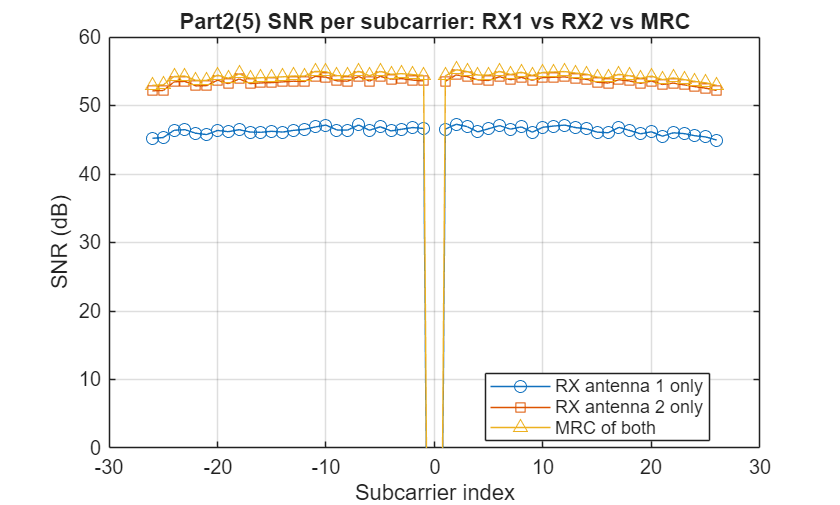

% Part2(5)
Es = 1;
SNR1_lin = zeros(1, Nfft);
SNR2_lin = zeros(1, Nfft);
SNR1_lin(toIdx(all_sc)) = (abs(H1_est(toIdx(all_sc))).^2 * Es) ./ Noise_power_1;
SNR2_lin(toIdx(all_sc)) = (abs(H2_est(toIdx(all_sc))).^2 * Es) ./ Noise_power_2;

% MRC: SNR_total = SNR1 + SNR2 (per subcarrier)
SNR_MRC_lin = SNR1_lin + SNR2_lin;
SNR_MRC_dB  = 10*log10(SNR_MRC_lin + eps);

figure;
plot(all_sc, SNR1_dB(toIdx(all_sc)), 'o-'); hold on;
plot(all_sc, SNR2_dB(toIdx(all_sc)), 's-');
plot(all_sc, SNR_MRC_dB(toIdx(all_sc)), '^-');
grid on;
xlabel('Subcarrier index');
ylabel('SNR (dB)');
title('Part2(5) SNR per subcarrier: RX1 vs RX2 vs MRC');
legend('RX antenna 1 only','RX antenna 2 only','MRC of both','Location','best');

ylim([0 60]);

For each subcarrier, the per-antenna SNR is $\text{SNR}_i(k)=|H_i(k)|^2E_s / N_0$. The first SNR is higher than the second one, which can be seen from the figure in part2 (1) directly.

The SNR with MRC is the sum of these two SNRs, which is $\text{SNR}_{MRC} =\text{SNR}_1 + \text{SNR}_2$. Hence, $\text{SNR}_{MRC}$ is larger than both two SNRs.

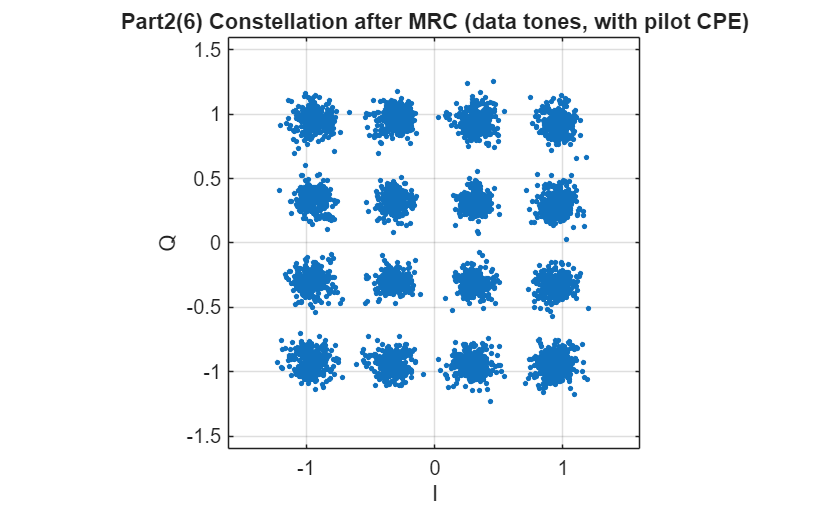

% Part2(6)
SNR1_lin = 10.^(SNR1_dB/10);
SNR2_lin = 10.^(SNR2_dB/10);

w1_data = SNR1_lin(toIdx(data_sc));   % 1×48
w2_data = SNR2_lin(toIdx(data_sc));   % 1×48

w1_mat = repmat(w1_data, numDataSym, 1);  % numSym×48
w2_mat = repmat(w2_data, numDataSym, 1);  % numSym×48

%    X_MRC = (w1*X1 + w2*X2) / (w1 + w2)
X_MRC_data = (w1_mat .* X_data1_CPEcorr + w2_mat .* X_data2_CPEcorr) ...
             ./ (w1_mat + w2_mat + eps);   % numSym×48

figure;
plot(real(X_MRC_data(:)), imag(X_MRC_data(:)), '.', 'MarkerSize', 8); grid on; axis equal;
xlabel('I'); ylabel('Q');
title('Part2(6) Constellation after MRC (data tones, with pilot CPE)');

xlim([-1.6 1.6]); ylim([-1.6 1.6]);

The constellation with MRC is more clear and the points are more concentrate compared to part 2 (4). This is because the SNR with MRC is higher than SNR1 and SNR2.